clear;
close all;

addpath('covid19pt-data/')
amostras = readtable('amostras.csv');
amostras.data = datetime(amostras.data, 'InputFormat','d-MM-uuuu')

amostras = 664×7 table
       data        amostras    amostras_novas    amostras_pcr    amostras_pcr_novas    amostras_antigenio    amostras_antigenio_novas
    ___________    ________    ______________    ____________    __________________    __________________    ________________________

    01-Mar-2020        25             25               25                 25                   0                        0            
    02-Mar-2020        70             45               70                 45                   0                        0            
    03-Mar-2020       131             61              131                 61                   0                        0            
    04-Mar-2020       171             40              171           

%plot(amostras.data, amostras.amostras)
casos = readtable('data.csv');
casos.data = datetime(casos.data, 'InputFormat','d-MM-uuuu');
casos.data_dados = datetime(casos.data_dados, 'InputFormat','d-MM-uuuu HH:mm');
casos([1,2,3,4,size(casos,1)],:) = []

casos = 664×93 table
       data             data_dados         confirmados    confirmados_arsnorte    confirmados_arscentro    confirmados_arslvt    confirmados_arsalentejo    confirmados_arsalgarve    confirmados_acores    confirmados_madeira    confirmados_estrangeiro    confirmados_novos    recuperados    obitos    internados    internados_uci    lab    suspeitos    vigilancia    n_confirmados    cadeias_transmissao    transmissao_importada    confirmados_0_9_f    confirmados_0_9_m    confirmados_10_19_f    confirmados_10_19_m    confirmado

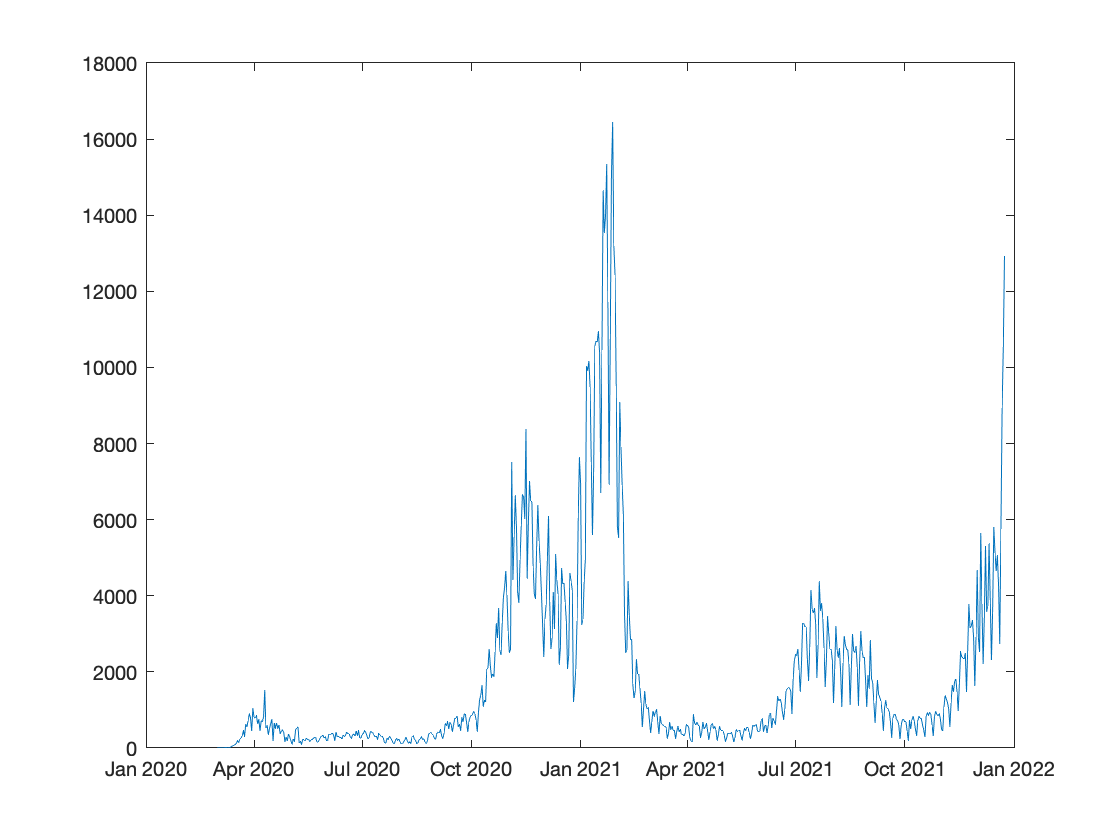

plot(casos.data, casos.confirmados_novos)

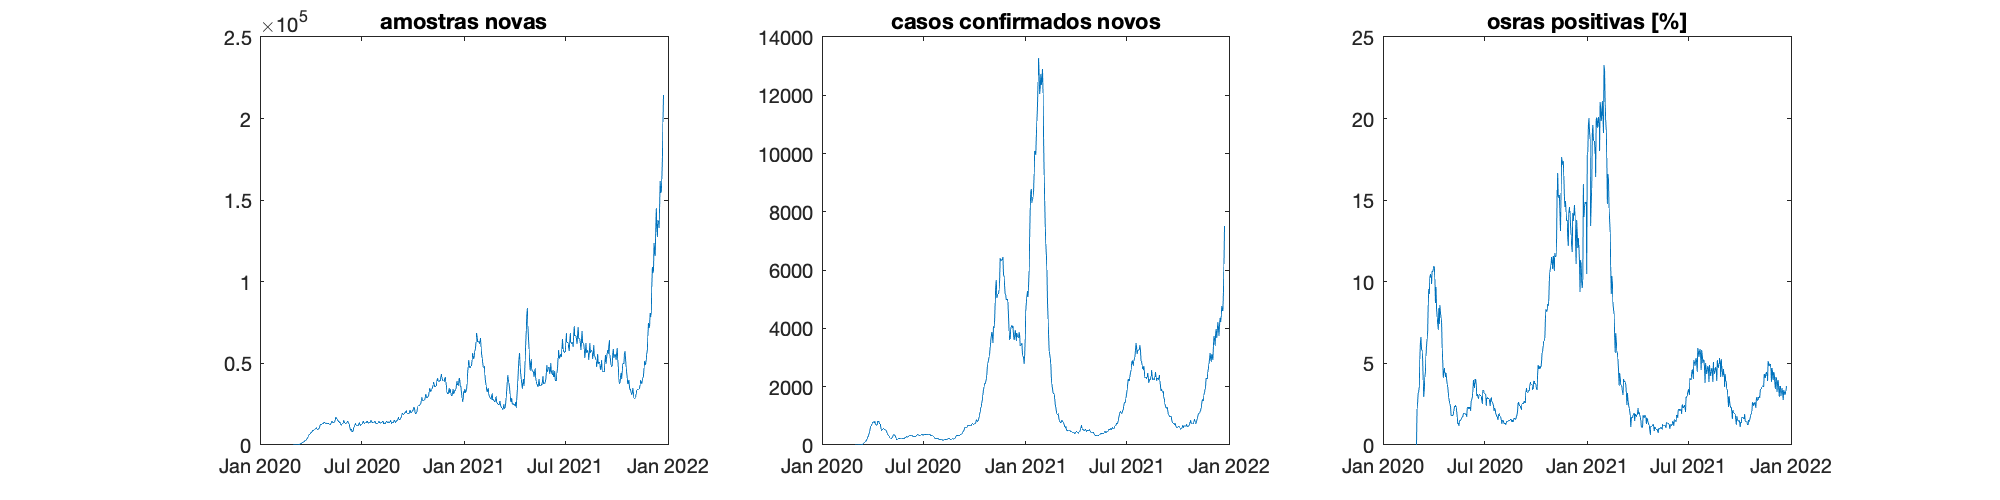

casos_positivos = (casos.confirmados_novos ./ amostras.amostras_novas);
f = figure();
subplot(1,3,1);
plot(amostras.data, movavg(amostras.amostras_novas, 'simple', 6));
title('amostras novas');
subplot(1,3,2);
plot(amostras.data, movavg(casos.confirmados_novos, 'simple', 6));
title('casos confirmados novos');
subplot(1,3,3);
plot(amostras.data, movavg(casos_positivos*100, 'simple', 6));
title('osras positivas [%]');
set(f, 'Position', [0 0 1000 250])

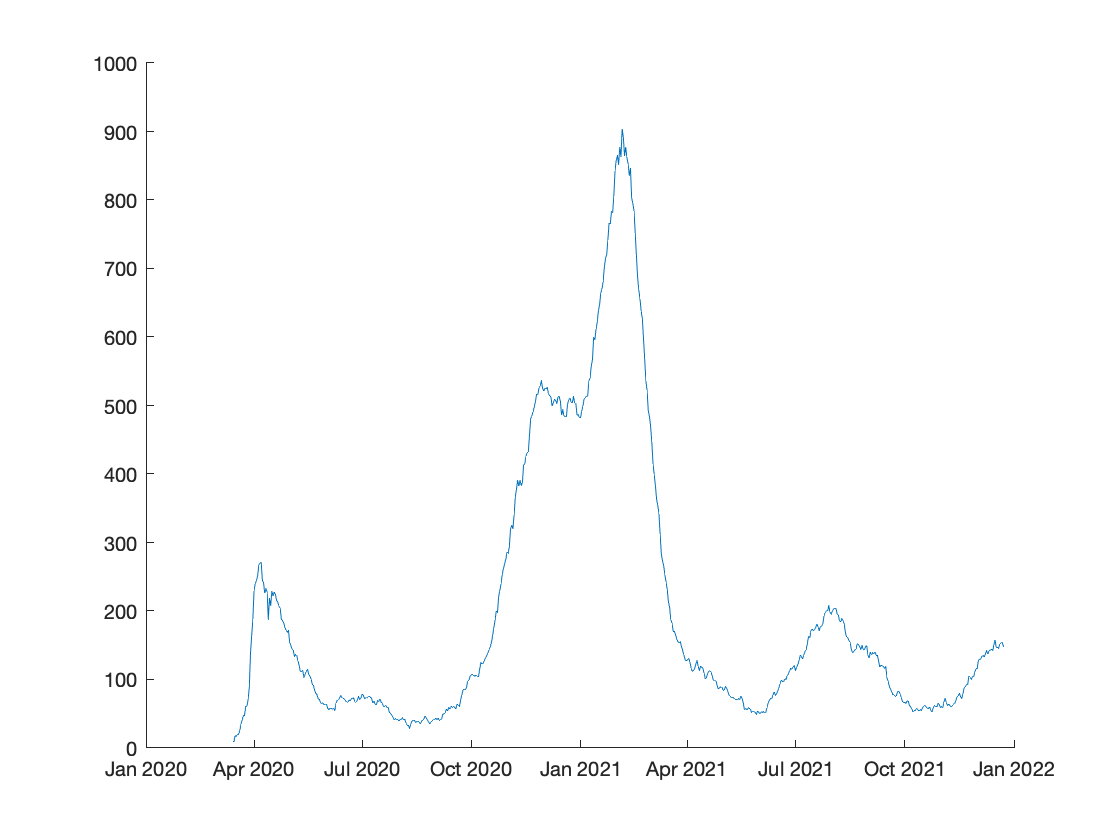

figure();
%internados = (casos.internados_uci ./ amostras.amostras_novas);
hold on
plot(amostras.data, casos.internados_uci);
%plot(amostras.data, casos.confirmados_novos);
hold off

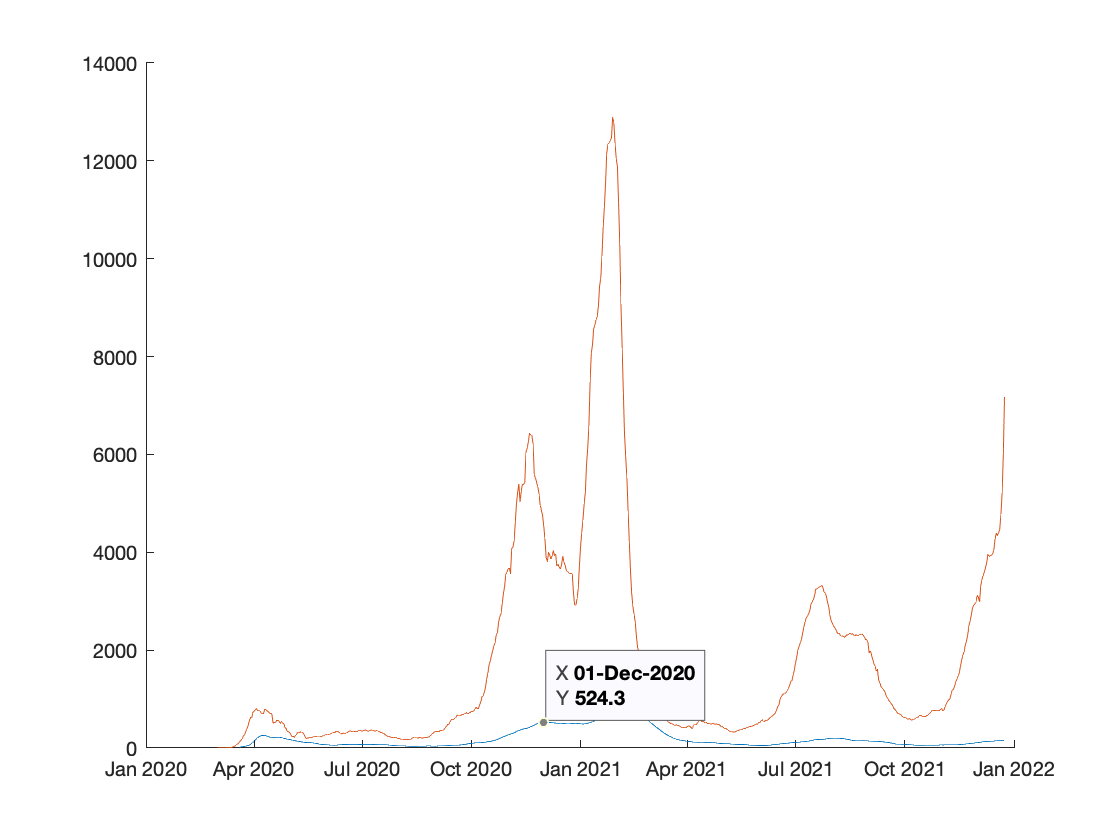

figure();
%internados = (casos.internados_uci ./ amostras.amostras_novas);
hold on
plot(amostras.data, movavg(casos.internados_uci, 'simple', 7));
plot(amostras.data, movavg(casos.confirmados_novos, 'simple', 7));
hold off

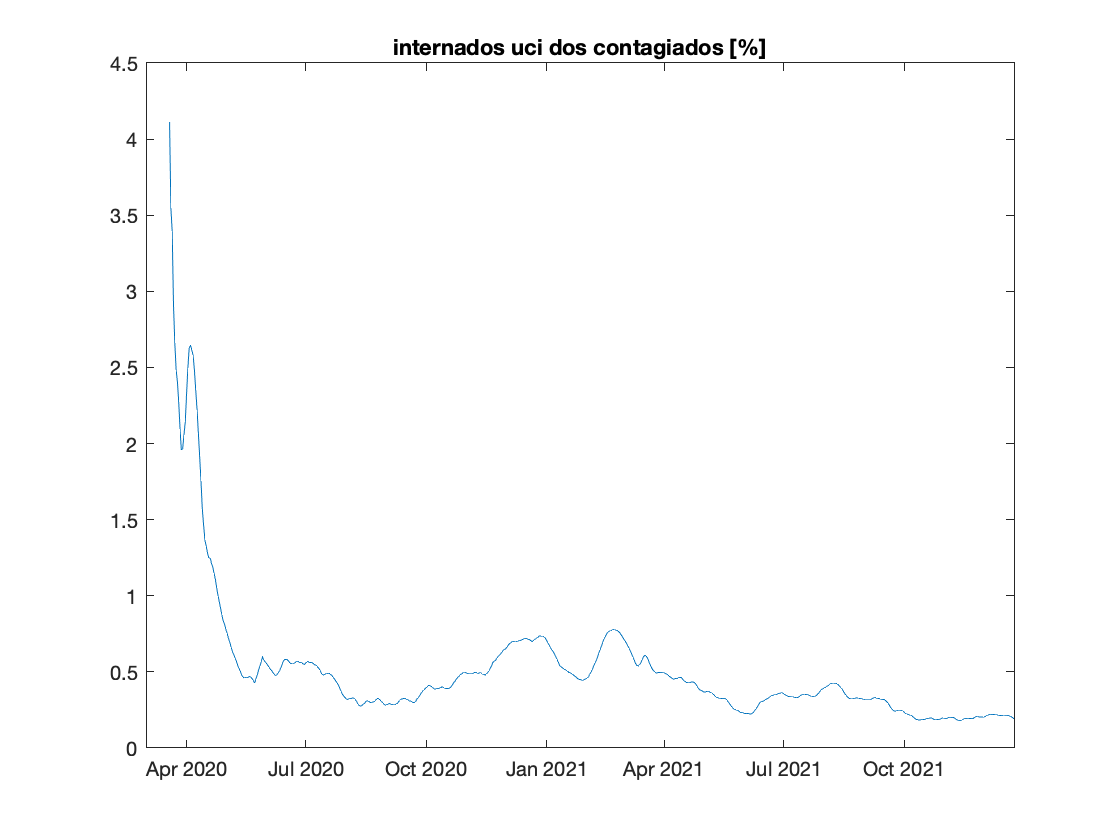


figure();
internados_uci = (casos.internados_uci ./ casos.ativos);
plot(amostras.data, movavg(internados_uci*100, 'simple', 6));
title('internados uci dos contagiados [%]');
xlim([amostras.data(1) amostras.data(size(amostras.data, 1))])

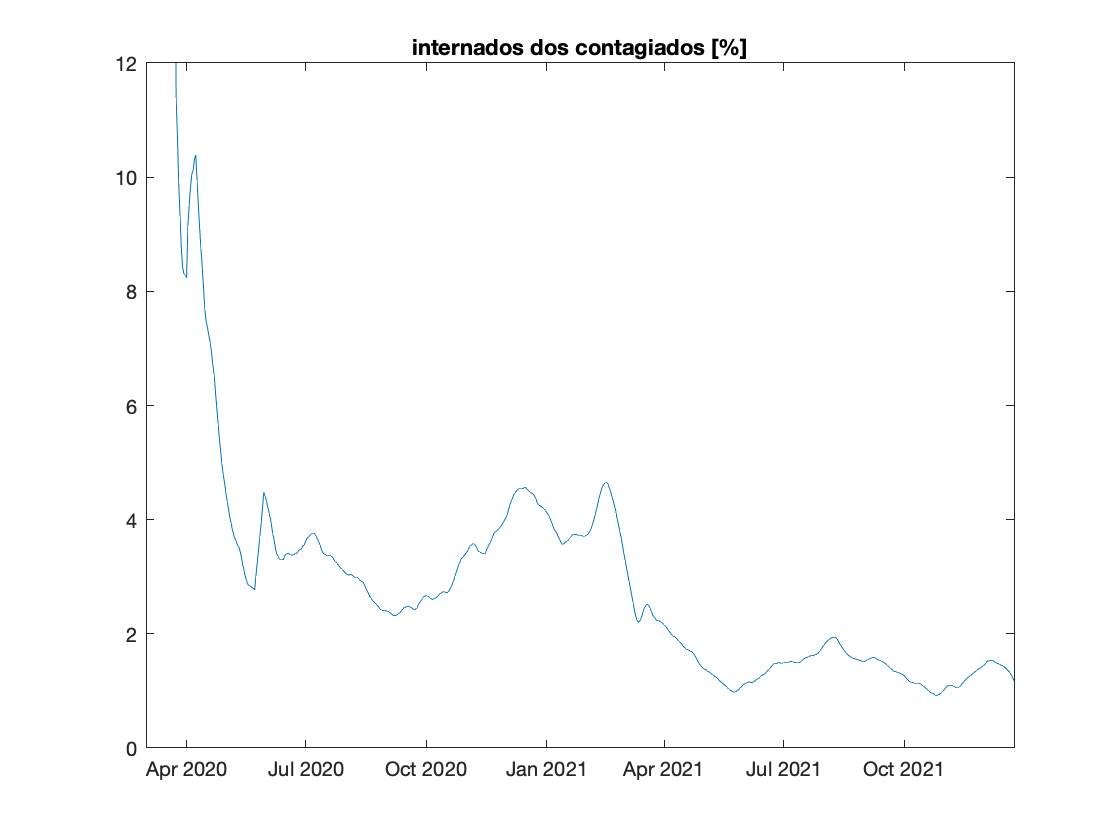

figure();
internados = (casos.internados ./ casos.ativos);
plot(amostras.data, movavg(internados*100, 'simple', 7));
title('internados dos contagiados [%]');
xlim([amostras.data(1) amostras.data(size(amostras.data, 1))])
ylim([0 12])